
RGB=imread("..\img\pzl_4_4.jpg");
I = rgb2gray(RGB);
gmag = imgradient(I);
imshow(gmag,[])
title('Gradient Magnitude')
se = strel('disk',20);
Io = imopen(I,se);

imshow(Io)
title('Opening')
Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title('Opening-by-Reconstruction')
Ioc = imclose(Io,se);
imshow(Ioc)
title('Opening-Closing')

Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
imshow(imgradient(Iobrcbr))
imshow(imsegkmeans(Iobrcbr,2),[])

title('Opening-Closing by Reconstruction')
fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title('Regional Maxima of Opening-Closing by Reconstruction')
se2 = strel(ones(5,5));
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);
fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(I,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')
bw = imbinarize(Iobrcbr);
imshow(bw)
title('Thresholded Opening-Closing by Reconstruction')
D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Watershed Ridge Lines')

open checkerboardPattern.pdf

N=4;
disp(strcat("..\img\pzl_",string(N),"_4.jpg"));

..\img\pzl_4_4.jpg


I=dip_GN_imread(strcat("..\img\pzl_",string(N),"_4.jpg"));
tic;
[a,c]=segmentation(I,2,5,0.3,60);
toc;

Elapsed time is 4.140816 seconds.


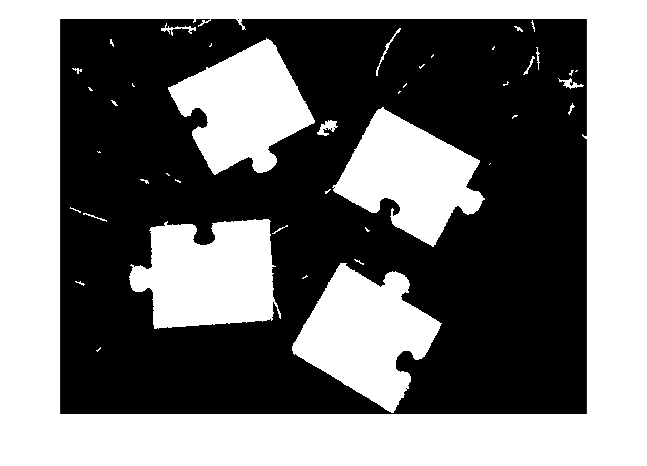

figure;
imshow(a);

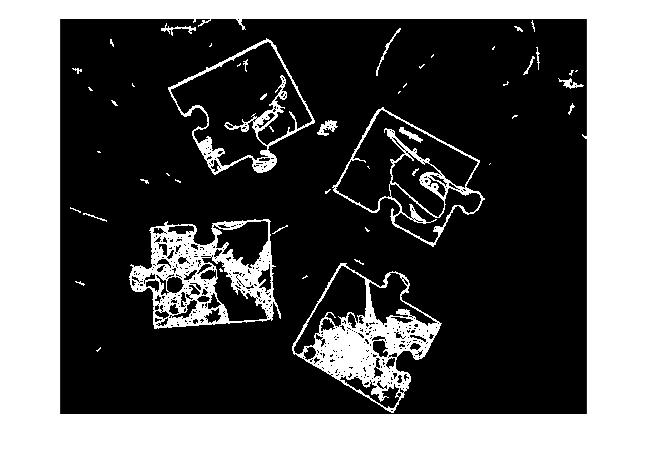

figure;
imshow(c);

tic;
d = cut_images(RGB,a,9,10);
toc;

Elapsed time is 0.483769 seconds.


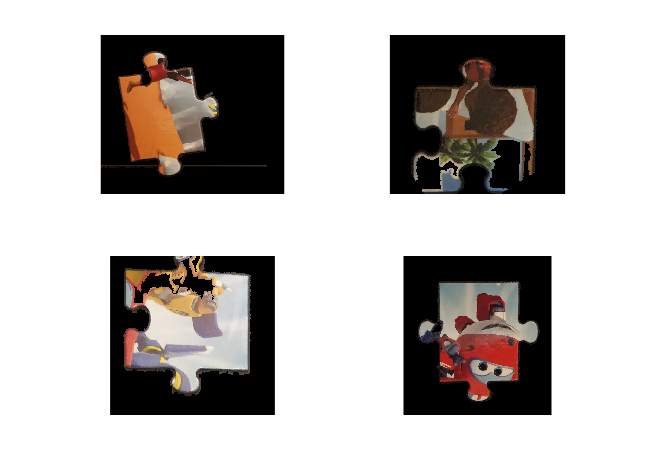

for i=1:N
    subplot(2,2,i);
    imshow(C{i});
end

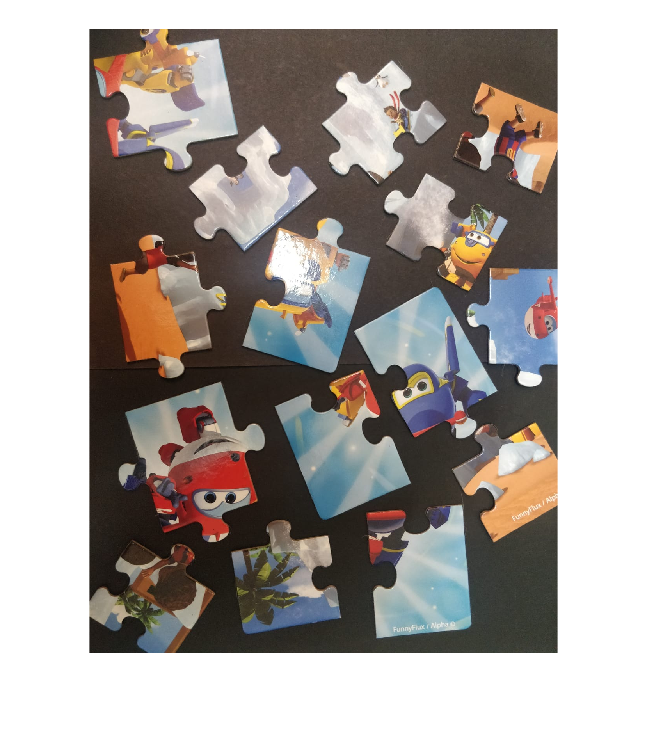

N=15;
RGB=imread("..\img\test_15_1.jpeg");
figure;
imshow(RGB)

% RGB = imread('kobi.png');
% RGB=imresize(RGB,0.1);

img=dip_GN_imread("..\img\test_15_1.jpeg");
% BW=edge(img,"prewitt");
tic;
BW= imgradient(img)>0.2;
% imshow(BW);
% imshow(imclose(BW,strel("rectangle",[2,2])));

dial = imdilate(BW,strel("rectangle",[2,2]));
% se = strel('disk',20);
% Iobrd = imdilate(BW,se);
% Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(BW));
% Iobrcbr = imcomplement(Iobrcbr);
% imshow(Iobrcbr)
% solidity = bwpropfilt(dial, 'Solidity', [0, 0.5]);
extent = bwpropfilt(dial, 'Extent', [0, 0.3]);
% area_filter = bwpropfilt(dial, 'Area', [1000, 65633]);
% imshow(BW);
% imshow(dial);
% imshow(solidity);
% imshow(extent);
% imshow(imdilate(extent,strel("rectangle",[7,7])));
ext_dial = imdilate(extent,strel("rectangle",[5,5]));


% imshow(area_filter);
% imshow(imfill(area_filter,"holes"));
% imshow(imfill(area_filter,8,"holes"));
% imshow(imfill(extent,"holes"));
% imshow(imfill(imfill(solidity,'holes'),"holes"));
% I = im2gray(im2single(RGB));
% evolved = activecontour(I,ext_dial,10,"Chan-vese","ContractionBias",-0.1);
mask = imfill(double(ext_dial),8,"holes");
% toc;
% tic;
% mask = imerode(mask,strel("rectangle",[10,10]));
% mask2 = imerode(mask,strel("rectangle",[100,100]));
% imshow(mask);
% imshow(bwareafilt(logical(mask),N));
% imshow(labled==6);
% imshow(labled);
% imshow(labeloverlay(RGB,mask));
% maskOpen = ~bwareaopen(~mask, 10);
distTrans = -bwdist(~mask);
% toc;
% imshow(maskOpen);
% imshow(distTrans,[]);
% Ld = watershed(distTrans);
% imshow(label2rgb(Ld))
% bw2 = mask;
% bw2(Ld == 0) = 0;
% imshow(bw2);
% tic;
extended_dist = imextendedmin(distTrans,60);
% toc;
% imshow(extended_dist);
% tic;
% imshowpair(mask,extended_dist,'blend');
D2 = imimposemin(distTrans,extended_dist);
% toc;
% tic;
Ld2 = watershed(D2);
% toc;
% tic;
bw3 = mask;
bw3(Ld2 == 0) = 0;
% imshow(bw3);
% toc;
% tic;
C = cut_images(RGB,bw3,N,50);
toc;

Elapsed time is 0.833783 seconds.


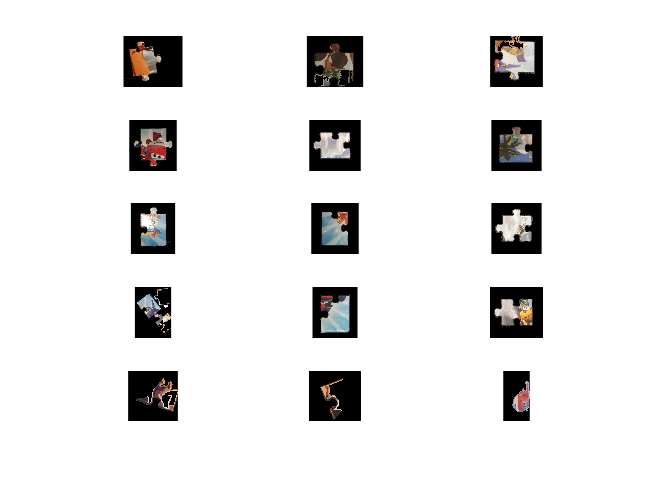

figure;
for i=1:N
    subplot(5,3,i);
    imshow(C{i});
end

% labled = bwlabel(bwareafilt(logical(mask),4));
% imshow(bwareafilt(logical(mask),4));
% extra_space = 50;
% imgCell = cell(N);
% for i=1:N
%     temp = labled==i;
%     [r,c]=find(labled==i);
%     
%     temp2 = RGB.*cast(temp,"like",RGB);
%     r_low = max(min(r)-extra_space,0);
%     r_high = min(max(r)+extra_space,size(temp,1));
%     c_low = max(min(c)-extra_space,0);
%     c_high = min(max(c)+extra_space,size(temp,2));
%     img_cut=temp2(r_low:r_high,c_low:c_high,:);
%     mask_cut = temp(r_low:r_high,c_low:c_high);
%     
%     BWedge = edge(mask_cut,"prewitt");
%     [H,T,R] = hough(BWedge);
%     peaks = houghpeaks(H,N*4);
%     lines = houghlines(BWedge,T,R,peaks);
%     angles = [lines.theta]';
%     [~,two_angles,~,~] = kmeans(angles,2);
%     a1 = mod(two_angles(1),90);
%     if (a1>45)
%         a1 = a1-90;
%     end
%     img_rot = imrotate(img_cut,a1,"crop");
%     cell{i} = img_rot;
%     subplot(2,2,i);
%     imshow(cell{i});
% %     hold on
% %     max_len = 0;
% %     for k = 1:length(lines)
% %        xy = [lines(k).point1; lines(k).point2];
% %        plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% %     
% %        % Plot beginnings and ends of lines
% %        plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
% %        plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
% %     
% %        % Determine the endpoints of the longest line segment
% %        len = norm(lines(k).point1 - lines(k).point2);
% %        if ( len > max_len)
% %           max_len = len;
% %           xy_long = xy;
% %        end
% %     end
%     
% end
% filled = imfill(evolved,"holes");
% imshow(evolved);
% imshow(filled);
% C = labeloverlay(RGB,filled);
% imshow(C)
% nrows = size(RGB,1);
% ncols = size(RGB,2);
% [X,Y] = meshgrid(1:ncols,1:nrows);
% I = im2gray(im2single(RGB));
% imshow(I);
% imshow(I-extent*0.5);
% featureSet = cat(3,I,X,Y,extent);
% uint8(V*255)
% L2 = imsegkmeans(I-extent*0.5,2,'NormalizeInput',true);
% C = labeloverlay(RGB,imfill(L2,"holes"));
% imshow(C)

thresh = uint8(3);
thresh2 = uint8(3);
a=fill_black(BW,2,thresh);
b = fill_white(a,3,thresh2);
imshow(a);
imshow(b);
imshow(BW);

% [H, S ,V]=rgb2hsv(RGB);
% S=uint8(S);
% L = imsegkmeans(S,2);
% B = labeloverlay(S,L);
% imshow(B)
% title('Labeled Image')



% wavelength = 2.^(0:5) * 3;
% orientation = 0:45:135;
% g = gabor(wavelength,orientation);
% 
% I = im2gray(im2single(RGB));
% gabormag = imgaborfilt(I,g);

montage(gabormag,'Size',[4 6])

nrows = size(RGB,1);
ncols = size(RGB,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
% featureSet = cat(3,I,gabormag,X,Y,BW);
RGB=imread("..\img\pzl_4_2.jpg");
contrasted = histeq(RGB,64);
imshow(contrasted);
[H, S ,V]=rgb2hsv(contrasted);
featureSet = cat(3,uint8(V*255),uint8(H*255));
% uint8(V*255)
L2 = imsegkmeans(uint8(V*255),2,'NormalizeInput',true);
C = labeloverlay(RGB,L2);
imshow(C)
title('Labeled Image with Additional Pixel Information')

RGB=imread("..\img\pzl_6_2.jpg");
imshow(autosegmentImage(RGB));